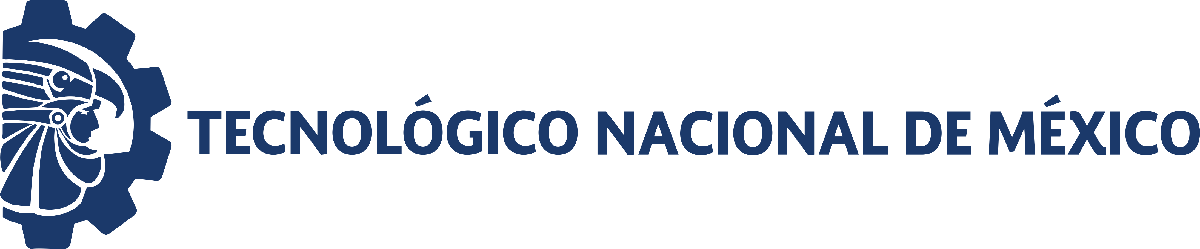                                 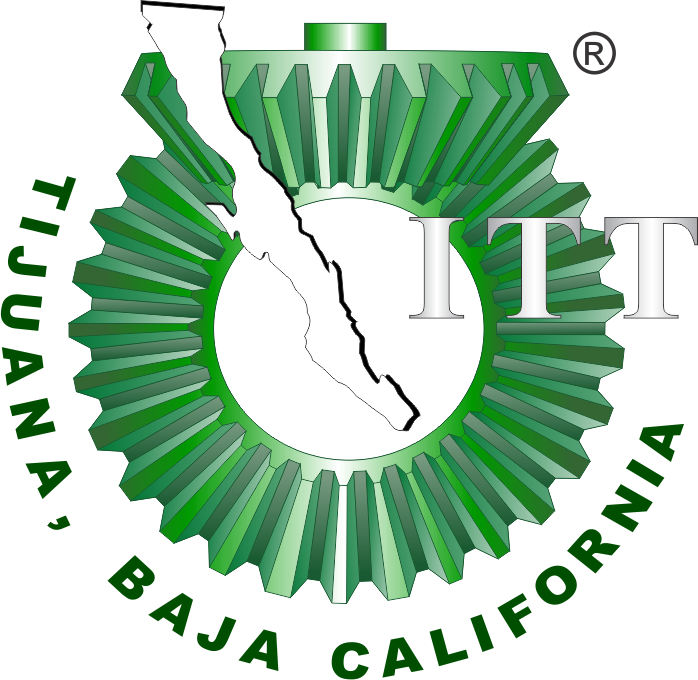

# Práctica 4: Regeneración de glóbulos rojos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

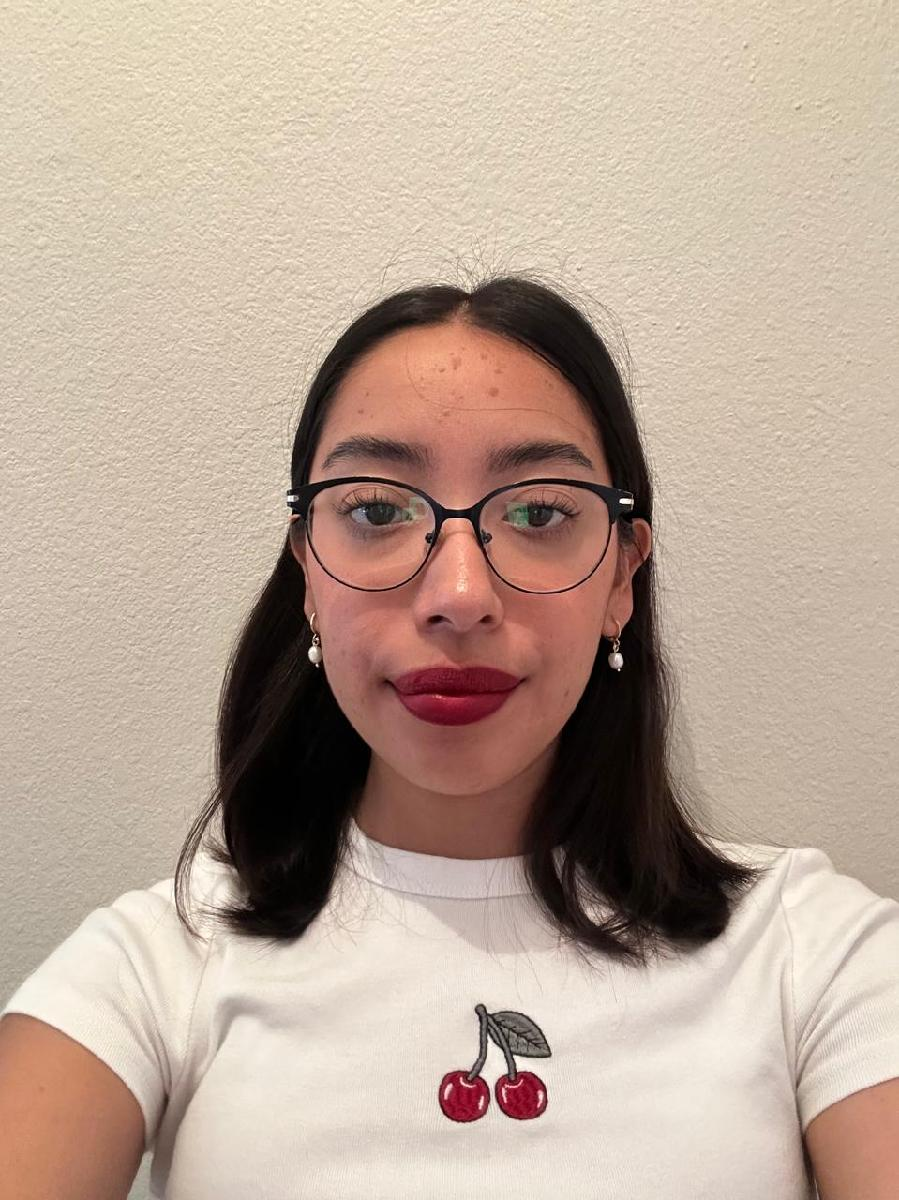

Nombre del alumno: **Valle Z. Flores Ana Kamila**

Número de control: **22211769**

Correo institucional:** l22211769@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = 180; %Tiempo de simulacion en días
dt = 1E-3; %Intervalo de integración para el métod de solución por diferencias finitas
n = round(tend/dt); %Cantidad de iteraciones para el método numérico

%Condiciones iniciales base para casa paciente
x1_0 = 59; x2_0 = 44; x3_0 = 885;

%Parámetros particulares para cada paciente
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.086; 0.243; 0.057];
beta = [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

seed = 22211769; %Semilla para asegurar reproducibilidad
rng(seed, 'twister')

%Intervalo de las condiciones iniciales
xmin = 0.99; xmax = 1.01;
interval = xmin + (xmax - xmin).*rand(numel(gamma),1);

%Condiciones iniciales de cada paciente
x1_0 = x1_0*interval; disp('x1(0)= '); disp(x1_0');...
x2_0 = x2_0*interval; disp('x2(0)= '); disp(x2_0');...
x3_0 = x3_0*interval; disp('x3(0)= '); disp(x3_0');

x1(0)= 
   59.5780   58.7446   59.3621   59.0041   59.4458   59.5282   59.1526   59.2395   59.4141   58.8162



x2(0)= 
   44.4310   43.8095   44.2700   44.0031   44.3325   44.3939   44.1138   44.1786   44.3088   43.8629



x3(0)= 
  893.6694  881.1693  890.4315  885.0617  891.6877  892.9231  887.2888  888.5931  891.2109  882.2433



## Caso: Sin transfusión sanguínea [u(t) = 0]

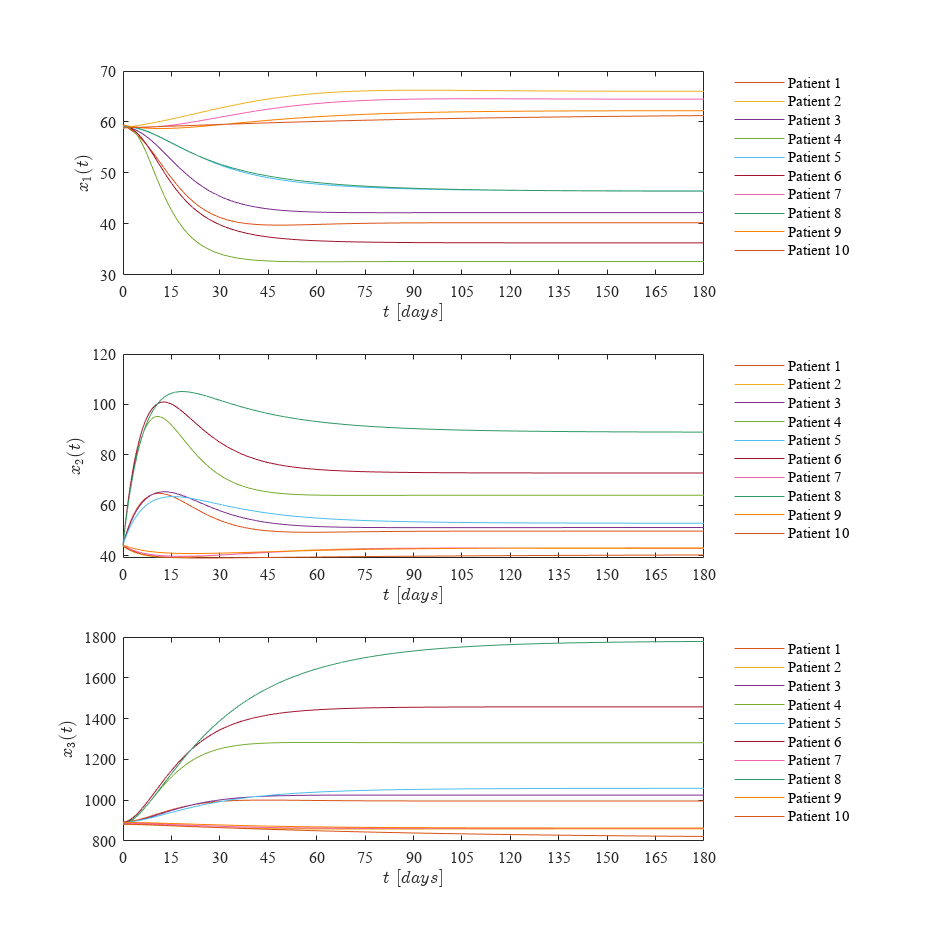

u = zeros(n+1,1); %No hay transfusión
fig = 1;
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Caso: Transfusión sanguínea [u(t) = 1 [t1,t2] ]

close all;
u = zeros(tend/dt + 1, 1);  
u(1:round(1/dt)) = 1;  
fig = 2;
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Función: Modelo matemático


$$\dot{x_1 } =\beta \left(X_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)x_1 \right)}{B_{\textrm{ase}} }$$



$$\dot{x_2 } =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$$\dot{x_3 } =\beta \left(k_2 x_2 -\alpha x_3 \right)-u\left(t\right)x_3$$


function [t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
%Parámetros fijos del sistema
    Base = 885.42; X0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
    t = (0:dt:tend)';
    n = round (tend/dt);
    x1 = zeros(n+1,1); x1(1) = x1_0;
    x2 = zeros(n+1,1); x2(1) = x2_0;
    x3 = zeros(n+1,1); x3(1) = x3_0;

    for i = 1:n %Método ded Euler (diferencias finitas)
        x1(i+1) = x1(i) + (beta*(X0 - k1*x1(i)) + gamma*(Base - x3(i))*(1-u(i))*x1(i)/Base)*dt;
        x2(i+1) = x2(i) + (beta*k1*x1(i) - k2*x2(i))*dt;
        x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i)) - u(i)*x3(i))*dt;
    end
end


## Función: Soluciones de tiempo

function plotdata(t,x1,x2,x3,fig)
    set(figure(fig),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,20,20])
    mycolors = [0.8500, 0.3250, 0.0980;  
    0.9290, 0.6940, 0.1250;  
    0.4940, 0.1840, 0.5560;  
    0.4660, 0.6740, 0.1880;
    0.3010, 0.7450, 0.9330;
    0.6350, 0.0780, 0.1840;  
    0.9490, 0.3765, 0.7020;  
    0.2000, 0.6000, 0.4000;
    1.0000, 0.5000, 0.0000;  
];

    subplot(3,1,1)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x1)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_1(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)

    subplot(3,1,2)
    hold on; grid off; box on;colororder(mycolors)
    plot(t,x2)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_2(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)

    subplot(3,1,3)
    hold on; grid off; box on;colororder(mycolors)
    plot(t,x3)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_3(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)

    if fig == 1
           exportgraphics(gcf,'Caso Sin transfusion.pdf','ContentType','Vector')
           exportgraphics(gcf,'Caso Sin transfusion.png','Resolution',300)
        elseif fig == 2 
            exportgraphics(gcf,'Caso Con transfusion.pdf','ContentType','Vector')
            exportgraphics(gcf,'Caso Sin transfusion.png','Resolution',300)
    end
  
end